clear; %Limpa todas as variáveis salvas no workspace
close all; %Fecha todos os gráficos abertos
clc; %Limpa o Command Window

%(J)     moment of inertia of the rotor     0.01 kg.m^2
%(b)     motor viscous friction constant    0.1 N.m.s
%(Ke)    electromotive force constant       0.01 V/rad/sec
%(Kt)    motor torque constant              0.01 N.m/Amp
%(R)     electric resistance                1 Ohm
%(L)     electric inductance                0.5 H


J = 0.01;
b = 0.1;
K = 0.01;
R = 1;
L = 0.5;
s = tf('s');
D = 0.1;


%%
%Sem atraso de transporte
motor_Tf = K/((J*s+b)*(L*s+R)+K^2);

motor_Tf


motor_Tf =
 
             0.01
  ---------------------------
  0.005 s^2 + 0.06 s + 0.1001
 
Continuous-time transfer function.



poles = pole(motor_Tf);
disp(poles)

   -9.9975
   -2.0025



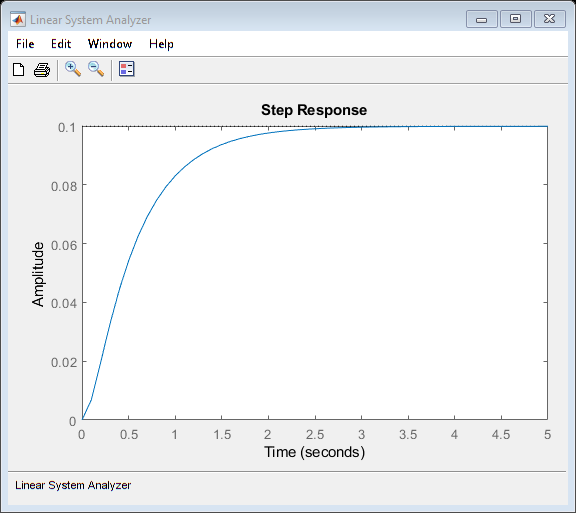

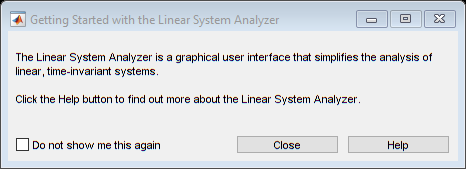

linearSystemAnalyzer('step', motor_Tf, 0:0.1:5);

stepinfo(motor_Tf)

ans = struct with fields:
        RiseTime: 1.1351
    SettlingTime: 2.0652
     SettlingMin: 0.0899
     SettlingMax: 0.0998
       Overshoot: 0
      Undershoot: 0
            Peak: 0.0998
        PeakTime: 3.6758


%%
%Com atraso de transporte de 1 segundo
motor_delay_Tf = K*exp(-1*s)/((J*s+b)*(L*s+R)+K^2)


motor_delay_Tf =
 
                         0.01
  exp(-1*s) * ---------------------------
              0.005 s^2 + 0.06 s + 0.1001
 
Continuous-time transfer function.



motor_delay_Tf


motor_delay_Tf =
 
                         0.01
  exp(-1*s) * ---------------------------
              0.005 s^2 + 0.06 s + 0.1001
 
Continuous-time transfer function.



poles = pole(motor_delay_Tf);
disp(poles)

   -9.9975
   -2.0025



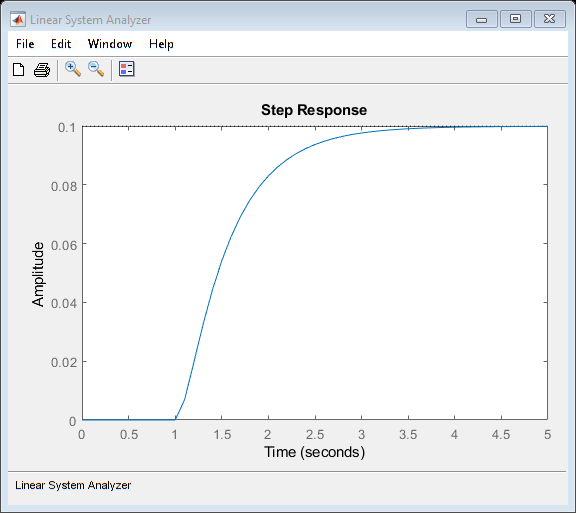

linearSystemAnalyzer('step', motor_delay_Tf, 0:0.1:5);

stepinfo(motor_delay_Tf)

ans = struct with fields:
        RiseTime: 1.1351
    SettlingTime: 3.0652
     SettlingMin: 0.0900
     SettlingMax: 0.0999
       Overshoot: 0
      Undershoot: 0
            Peak: 0.0999
        PeakTime: 9.2956


[y,t]= step(motor_delay_Tf); %get the response of the system to a step with amplitude SP
sserror=abs(1-y(end))

sserror = 0.9002

%%
%Com atraso de transporte de 1 segundo usando a aproximação de Padé de
%1ºgrau(e^x = 2+x / 2-x).
motor_Pade_Tf1 = K*(2 - s)/(((J*s+b)*(L*s+R)+K^2)*(2 + s));

motor_Pade_Tf1


motor_Pade_Tf =
 
               -0.01 s + 0.02
  ----------------------------------------
  0.005 s^3 + 0.07 s^2 + 0.2201 s + 0.2002
 
Continuous-time transfer function.



poles = pole(motor_Pade_Tf1);
disp(poles)

   -9.9975
   -2.0025
   -2.0000



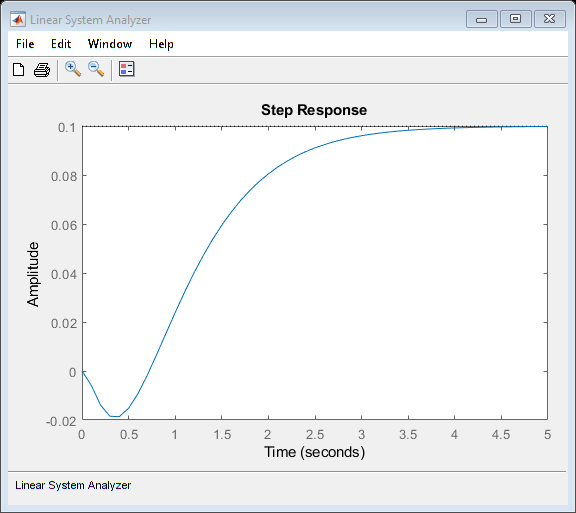

linearSystemAnalyzer('step', motor_Pade_Tf1, 0:0.1:5);

[y,t]= step(motor_delay_Tf); %get the response of the system to a step with amplitude SP
sserror=abs(1-y(end))

sserror = 0.9002


motor_Pade_Tf2 = K*(2 - D*s)/(((J*s+b)*(L*s+R)+K^2)*(2 + D*s));
motor_delay_Tf2 = K*exp(-1*s)/((J*s+b)*(L*s+R)+K^2)

numg = [-1 20];
deng = [0.5 16 130 200.2];

numroots = roots(numg);
denroots = roots(deng);

motor_Pade_Tf2
poles = pole(motor_Pade_Tf2);
disp(poles)
linearSystemAnalyzer('step', motor_Pade_Tf2, 0:0.1:5);
[y,t]= step(motor_delay_Tf2); %get the response of the system to a step with amplitude SP
sserror=abs(1-y(end))

rlocus(motor_Pade_Tf)

%%
%saida como a posição
%motor_pos_Tf = K/(((J*s+b)*(L*s+R)+K^2)*s)
%motor_pos_Tf
%poles = pole(motor_pos_Tf);
%disp(poles)
%linearSystemAnalyzer('step', motor_pos_Tf, 0:0.1:5);